clear all;

Инициализация задачи

lambda = -1.5; mu = 8;
F= @(t,y) lambda*y;    G = @(t,y) mu*y;
%sde = @(t,y) F(t,y)dt + G(t,y)dW;

Начальные условия

%randn("state",100);
rng("default");
t_0 = 0;
Yzero = 1;
h = 2^(-2);
rightBorder = 2;
dW = sqrt(h)*randn(1,(rightBorder-t_0)/h);
W = [0 cumsum(dW)];

"Точное решение"

Ytrue = Yzero*exp((F(0,Yzero) - 0.5*G(0,Yzero)^2)*(0:h:rightBorder) + G(0,Yzero)*W);
hold on
plot ([0:h:rightBorder], Ytrue, '-m');

Решение численными методами

tic
[T,Y] = EulerMaruyama(F, G, h,t_0, Yzero, rightBorder);
toc

Elapsed time is 0.045988 seconds.


[T1,Y1] = RKCforSDE(F, G, h, t_0, Yzero, rightBorder, 2, 0);
toc

Elapsed time is 0.103490 seconds.


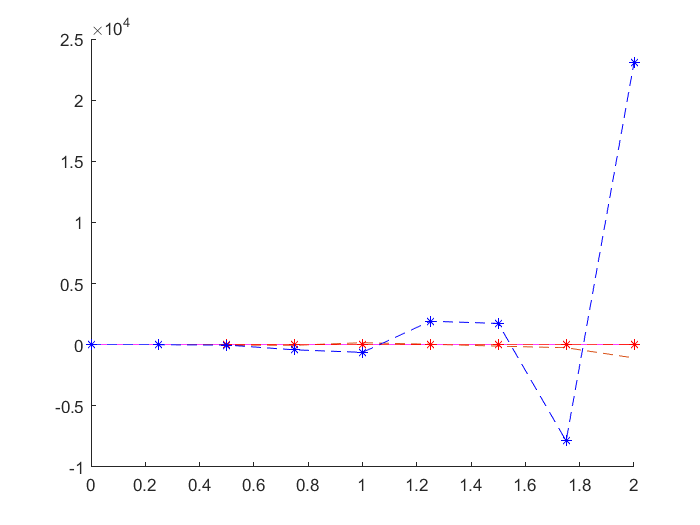

[T2, Y2] = Milstein(F, G, h, t_0, Yzero, rightBorder);
plot (T,Y, '--');
plot (T1,Y1, 'r--*');
plot (T2,Y2, 'b--*');
hold off

Средние квадраты

numExp = 100;
rightBorder = 50; 
h = h*2

h = 0.5000

tic
for i=1:numExp
    [Tem, EM(i,:)] = EulerMaruyama(F, G, h, t_0, Yzero, rightBorder);
end

for i=1:length(Tem)
    meanY(i) = mean(EM(:,i).^2);
end
toc

Elapsed time is 1.089987 seconds.


%%////////////
for i=1:numExp
    [Trock, Rock(i,:)] = RKCforSDE(F, G, h, t_0, Yzero, rightBorder, 2, 0.25);
end

for i=1:length(Trock)
    meanYrock(i) = mean(Rock(:,i).^2);
end
toc

Elapsed time is 2.174233 seconds.


%%///////////
h = h*2

h = 1

for i=1:numExp
    [hTem, hEM(i,:)] = EulerMaruyama(F, G, h, t_0, Yzero, rightBorder);
end

for i=1:length(hTem)
    meanhY(i) = mean(hEM(:,i).^2);
end
toc

Elapsed time is 3.259990 seconds.


%%/////////
for i=1:numExp
    [hTrock, hRock(i,:)] = RKCforSDE(F, G, h, t_0, Yzero, rightBorder, 2, 0.25);
end

for i=1:length(hTrock)
    meanhYrock(i) = mean(hRock(:,i).^2);
end
toc

Elapsed time is 4.354016 seconds.


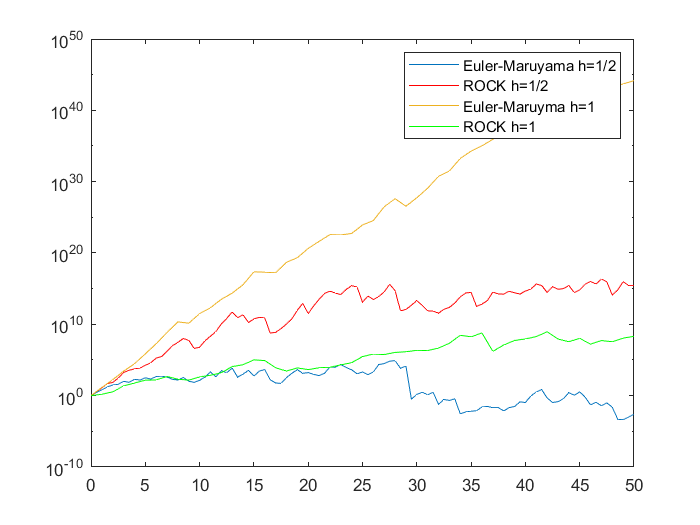

%%///////
figure
semilogy(Tem, meanY, Trock,meanYrock, 'r', hTem, meanhY, hTrock,meanhYrock, 'g');
legend("Euler-Maruyama h=1/2", "ROCK h=1/2", "Euler-Maruyma h=1", "ROCK h=1");
hold on